# Control and Instrumentation Lab Assignment 5

**SWARNENDU PAUL 19EE3FP18**

## Root Locus Technique

**Question 1-6(session5.docx)**

Question 1.

Characteristic equation


$$s(s+2)(s+3)+K(s+1)=0$$
 

tf1=zpk(-1,[0,-2,-3],1)

tf1 =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



Poles of this transfer function will be the K=0 points

Poles=pole(tf1)

Poles =      0
    -2
    -3


And zeros of this transfer function will be the $K=\infty$ points.

Zeros=zero(tf1)

Zeros = -1

As there is only one zero so other 2 $K=\infty$ points will be at $\infty$

Now lets construct the root-locus of the given transfer function.

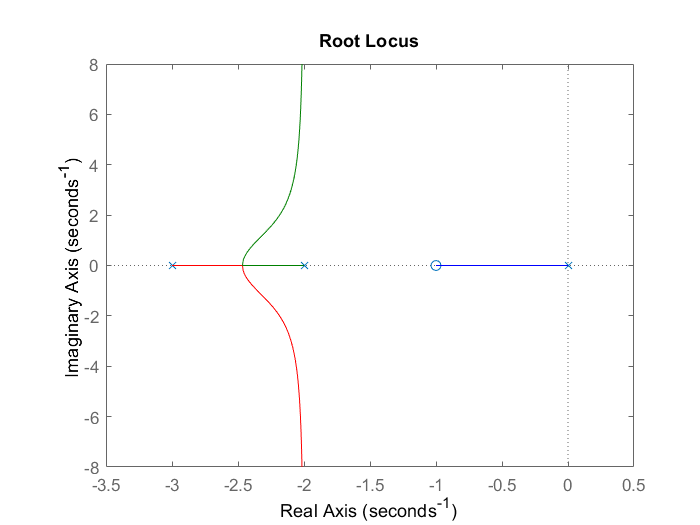

figure;
rlocus(tf1)

So the pole at 0 reaches 1 as K goes to $\infty$ and other two poles goes to $\infty$ with asymptotes at -2 with angles $90^\circ$ and $270^\circ$.

Question 2.

Characteristic equation


$$s(s+2)(s+1+j)(s+1-j)+K=0$$


transfer function:

tf2=zpk([],[0,-2,-1+1i,-1-1i],1)

tf2 =
 
            1
  ----------------------
  s (s+2) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



Root locus:

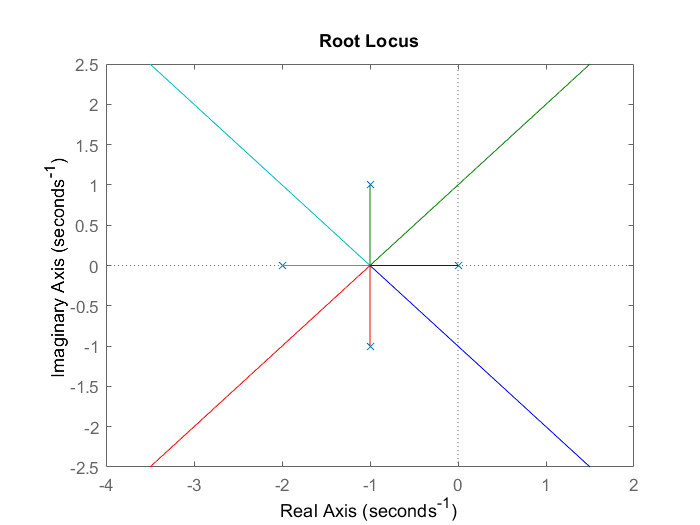

figure;
rlocus(tf2)

As we can observe root locus is symmetric about the point -1. 

Question 3.

Characteristic equation


$$s(s+4)(s^2+2s+2)+K(s+1)=0$$


transfer function:

tf3=zpk(-1,[0,-4,-1+1i,-1-1i],1)

tf3 =
 
          (s+1)
  ----------------------
  s (s+4) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



centroid is at $\frac{0-4-1-1+1}{4-1} = -\frac{5}{3}$ **which is the intersect of asymptotes.**

And, **asymptote angles are **$\theta = \frac{(2q+1)180^\circ}{4-1} = 60^\circ,180^\circ,300^\circ$ 

Root locus:

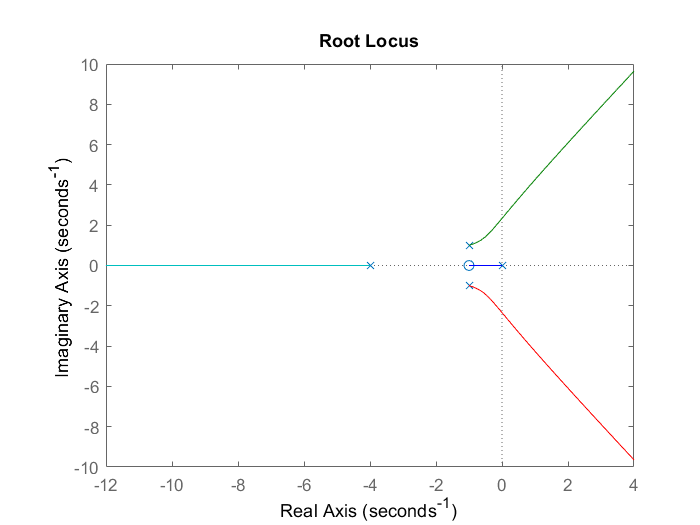

figure;
rlocus(tf3)

As we can observe 3 asymptotes that intersect at centroid in the root locus plot.

Question 4.

Characteristic equation:


$$s(s+3)(s^2+2s+2)+K=0$$


transfer function:

tf4=zpk([],[0,-3,-1+1i,-1-1i],1)

tf4 =
 
            1
  ----------------------
  s (s+3) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



If odd number of the open loop poles and zeros exist to the left side of a point on the real axis, then that point is on the root locus branch. So, **on real axis, root loci will be present in between two poles 0,-3.**

For the departure angle of the pole $s_1=-1+i$,

Pole at 0, makes $135^\circ$ with $s_1$, pole at -3 makes $tan^{-1}\frac{1}{2}$ angle with $s_1$, pole at $-1-i$ makes $90^\circ$ with $s_1$

So **angle of departure = **$180^\circ - 135^\circ-90^\circ-tan^{-1}\frac{1}{2} = -71.56^\circ$ 

Root locus:

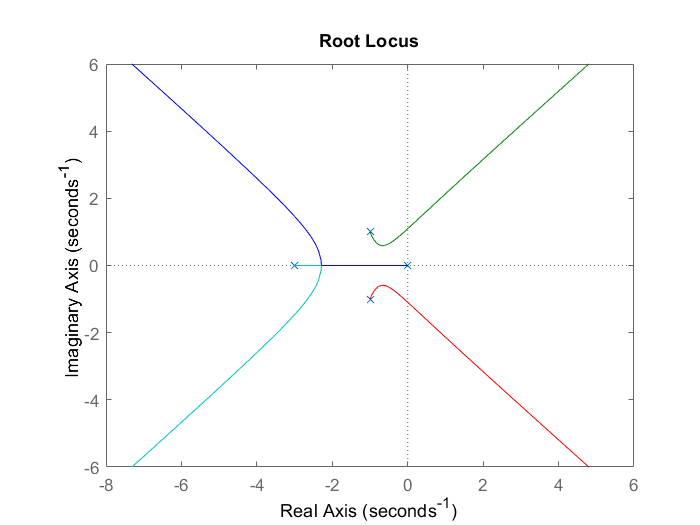

figure;
rlocus(tf4)

Question 5.

Characteristic equation:


$$s(s+4)(s^2+4s+20)+K=0$$


transfer function:

tf5=zpk([],[0,-4,-2+4i,-2-4i],1)

tf5 =
 
             1
  -----------------------
  s (s+4) (s^2 + 4s + 20)
 
Continuous-time zero/pole/gain model.



To determine the intersection with imaginary axis we use Routh-Hurwitz table and find value of K for which a row is 0. At K=260 we determine two poles will be on imaginary axis.

Putting the value in characteristic equation, **intersections with imaginary axis are at **$\sqrt{10}i$** and **$-\sqrt{10}i$

To determine the breakaway point we write the equation as, $K=-(s^4+8s^3+36s^2+80s)$ and then differentiate the RHS.

 $\frac{dK}{ds}=0$ has a root at $s=-2$ so putting s=-2 we get K=64. Hence **-2 is a breakaway point on real axis.**

Root locus:

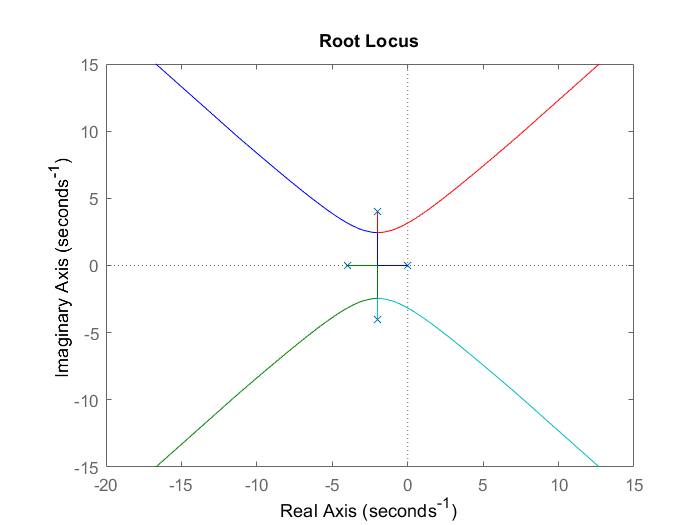

figure;
rlocus(tf5)

Question 6.

Characteristic equation:


$$s(s+5)(s+6)(s^2+2s+2)+K(s+3)=0$$


transfer function:

tf6=zpk(-3,[0,-5,-6,-1+1i,-1-1i],1)

tf6 =
 
             (s+3)
  ----------------------------
  s (s+5) (s+6) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



Poles at $K=0$ are $0,-5,-6,-1+i,-1-i$ and $K=\infty$ are $-3,\infty,\infty,\infty,\infty$

Hence we habe 5 root locus branches, 4 of them will go to $\infty$ as we increase $K$.

If odd number of the open loop poles and zeros exist to the left side of a point on the real axis, then that point is on the root locus branch. So, **on real axis, root loci will be present in between poles **$0,-3$ **and **$-5,-6$.

Centroid $\alpha = 2.5$ and angle of asymptotes $45^\circ,135^\circ,225^\circ,315^\circ$

There will be a break-away point between -5 and -6

Angle of departure for $-1+i$ is $180^\circ-(180^\circ-tan^{-1}1)-90^\circ-tan^{-1}\frac{1}{4}-tan^{-1}\frac{1}{5}+tan^{-1}\frac{1}{2} = -43.78^\circ$ 

So the root locus of pole at 0 will end at -3.

Pole at $-1+i$ will start with $-43.78^\circ$ angle and eventually follow the $45^\circ$ asymptote from centroid.

Pole at $-1-i$ will follow the $-1+i$ locus reflected w.r.t real axis.

Pole at -5 and -6 will break-away in between -5 and -6 and follow the other 2 asymptotes.

Now lets observe the root-locus:

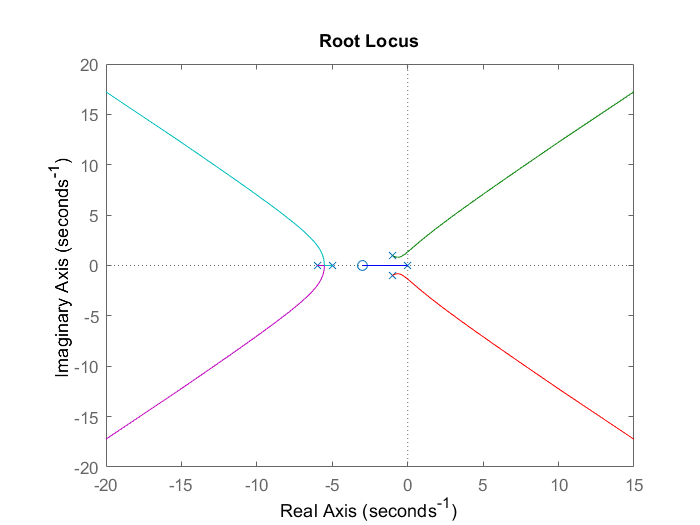

figure;
rlocus(tf6)